# Assignment: EPO4, Module 1, Machine learning

***Important Note:*** *Dear students, Here, in this live script, we have tried to guide you through the steps you need to take to complete the first assignment. We have included part of the code for you and you need to complete the rest denoted by "% your code here ". You should first uncomment those and then complete them.. This file is just to help you, feel free to change any line of code or use other functions, as long as it's correct and provides the expected results. Working in a live script is very similar to a normal script. The text will be treated as comment. When you are done, you can export this live script as Word or LaTeX and add it as an appendix to your midterm report for module 1.  You can also use the figures in the main part of your midterm report. If a function is new for you type "doc function_name" in the command window to see its detail and examples. *

## 3.4 Assignment

There are many data repositories online that are typically used to benchmark machine learning algorithms. One of them is the [UC Irvine Machine Learning Repository](http://archive.ics.uci.edu/ml/index.php). It maintains 497 datasets that can be used for different learning tasks like regression and classification. In this module, you will use the Parkinson Speech Dataset with multiple types of sound recordings. This dataset consists of two subsets of data. Here, you will only use the set called “Train Data”. We already prepared it for you and you can download it from Brightspace. The file is called Data_UCI_EPO4.mat.

## 3.4.1 Lab tasks

This dataset consists of 40 subjects, 20 patients suffering from Parkinson’s disease (Patients in the dataset), and 20 healthy volunteers (Controls in the dataset). For these assignments, it is not relevant to consider the patients separately from the controls. This information can be ignored, but it is mentioned here for completeness.

Each subject was asked to produce the following sounds:

- Sustained vowel a

- Sustained vowel o

- Sustained vowel u

- Numbers from 1 to 10 (N1-N10 in the dataset)

- 10 different words (Word1 - Word10 in the dataset)

Each sound is characterized by 25 different features that are included in the dataset as a matrix of 40*25.

To find out how these features were extracted, check the following paper, available in Brightspace:

Erdogdu Sakar B., Isenkul M., Sakar C.O., Sertbas A., Gurgen F., Delil S., Apaydin H., Kursun O., “Collection and Analysis of a Parkinson Speech Dataset with Multiple Types of Sound Recordings”,IEEE Journal of Biomedical and Health Informatics, vol. 17(4), pp. 828-834, 2013.

The dataset contains the Subject_Label, which indicates whether the subject is a patient or a control. For the assignments, this label information should not be relevant for the problem you need to solve. In fact, the classification should work for both control and patient data. (Optional) It might be that the performance is lower for patient data. Keep this in mind when evaluating the performance of your algorithm. For instance, you could split both groups and evaluate the performance separately.

For your midterm report, you need to justify every step in the design, for both assignments separately. Start from the separation of training and test set, your validation scheme, the classifier that you select, and the performance evaluation. Remember to always report the performance on an independent test set. 

## Task 1: Words vs. vowels classification 

The first task is to design a binary classifier to discriminate between one word and one vowel of your choice. Here you can use as a word any number if you find that it can be better distinghuish from a vowel. Ideally, you should be able to separate any vowel from any word, but if you find that one particular word or number leads to the best performance, go ahead and use it but always justify your selection. This will help you in module 2, when selecting your dictionary of commands. You can do this by selecting pairs at the time. For example, N1 and the vowel a first, then other pair and so on. You could, for example, classify between a and all the words, one word at the time, and select which word leads to the best performance. Remember, for this assignment you do not need to select all the words at once, since here you are dealing with a binary problem.

### Load Data

Let's load the dataset. You first need to download the data from Brightspace and put in in the same directory as this live script.

%% Load dataset
load Data_UCI_EPO4.mat;

As you can see in the workspace, we have a matrix for each vowel, word or number. The matrices contain 40 samples and 25 features. 

The first step is to make our training and test data. For this task, and for now, we decide to classify vowel "A" from word 1 "Word1". We should put the matrices for these two classes in one data matrix to form the complete data matrix. The data matrix will then be of size 80 (samples) by 25 (features).

sel1= A;
sel2= Word1;

% Data matrix for the selected words/vowels/numbers
X = [sel1;sel2]; 

now we should make the output labels, a 80*1 vector. We assign vowel "A" to class 1 and word 1 to class 2.

Y = [ones(40,1);2*ones(40,1)]; 

### Train-test Split

Let's split the data into two sets, the training set (70%) for training the classifier model and test set  (30%) for testing the model. We will do this in several steps: first we loop through all the classes, for each class we first find the indices of data samples belonging to that class and the shuffle them for a nice mix, next we use the first 70% of the samples for training and the rest for test.

percent_train_split=70/100;
train_id=[];
test_id=[];
num_classes=length(unique(Y)); 

% loop through the classes
for i=1:num_classes 
    % % finding the indices belonging to each class: use find()
    % % your code below
    ind_i=find(Y==i) ;
    
    % %shuffling the indice
    ind_i_perm=ind_i(randperm(length(ind_i)));
    
    % % the split point for train test
    ind_split=round(percent_train_split*length(ind_i_perm));
    
    % % adding the train ids to the the previous ids 
    train_id=[train_id;ind_i_perm(1:ind_split)];
    
    % % adding the test ids to the the previous ids 
    test_id=[test_id;ind_i_perm(ind_split+1:end)];
    
end

### Splitting the data

You can use the train and test ids (for rows!) to split the train and test data

% % splitting the inputs
% complete the codes below
Xtrain=X(train_id, :);
Xtest=X(test_id, :);

% % splitting the labels
Ytrain=Y(train_id);
Ytest=Y(test_id);

### Standard Normalization

Next we should performing standard normalization on train data and finding the save its mean and standard deviation, use "zscore()" function here.

[Xtrain,mu_train,sigma_train]=zscore(Xtrain);

we should perform any changes we make on training data on the test data too. using the mean and standard deviation of the training data to the test data too

Xtest=zscore(Xtest);

### Feature Selection using mRMR

Here we will use a feature selection method  called Minimum Redundancy Maximum Relevance (mRMR). As you can already imagine, this methodology finds the most relevant features, while minimizing their redundancy. This methodology is based on formulations of mutual information between the features and the targets y. For now, we will not dig into the theory behind this approach but if you are interested, you can read the paper by C. Ding and H. Peng, entitled “Minimum Redundancy Feature Selection from Microarray Gene Expression Data” that you can find on Brightspace.

In this module, you can use the Matlab function "fscmrmr()" for this part:

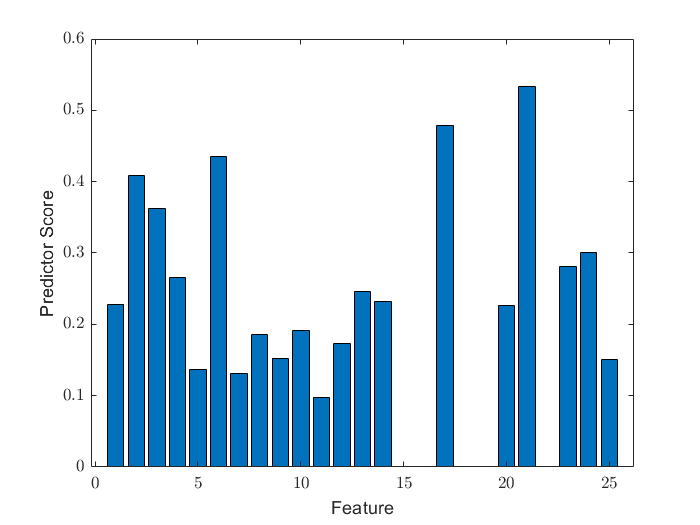

[idx,scores] = fscmrmr(X,Y);
bar(idx,scores(idx))% Create bar graph
xlabel('Feature')
set(gca,'TickLabelInterpreter','latex');
ylabel('Predictor Score'); hold off;

you can select the features with higher importance for the rest of this assignment but for now we will just keep all the features.

### Training

We'll now train a random forest classifier for classification of these two classes. You can do this in MATLAB using "TreeBagger()" function. let's use 20 trees and don't forget to set 'Method' to 'classification'.

% This makes sure we get the same results every time we run the code.
rng default

% How many trees do you want in the forest? 
nTrees = 20;
 
% Train the TreeBagger (Random Forest).
model = TreeBagger( nTrees,Xtrain,Ytrain ...
    , 'Method', 'classification');

you can try random forests with various number of trees or set other variables like "model = TreeBagger(nTrees,Xtrain,Ytrain ..., 'Method', 'classification','InBagFraction',0.5,'MaxNumSplits',5);" for better performance. 

### Testing the model on test data

First use model.predict() to predict the output values for test data. and then use "str2double" to turn them into doubles.

Ytest_pred_str=model.predict(Xtest);
Ytest_pred=str2double(Ytest_pred_str);

### Turn the numerical outputs to categorial

To make the confusion matrix, we first need to replace the current numerical labels by categorical variables. You can do this by first creating matrices filles with zeros of size: number of samples by number of classes. Next for both true output and predicted output we loop through the classes and for each we set the correponding row and the columns with those outputs equal to one.

Ytest_cat=zeros(num_classes, length(Ytest));
Ytest_pred_cat=zeros(num_classes, length(Ytest_pred));

for i=1:num_classes
    Ytest_cat(i, Ytest==i) = 1;
    Ytest_pred_cat(i, Ytest_pred==i) = 1;
end

### Plot confusion matrix

you can use the "plotconfusion()" function to plot the confusion matrix. Note that the confusion matrix is sufficient for this task but if you are interested you can also calculate the performance metrics:Sensitivity, Specificity, and Accuracy.

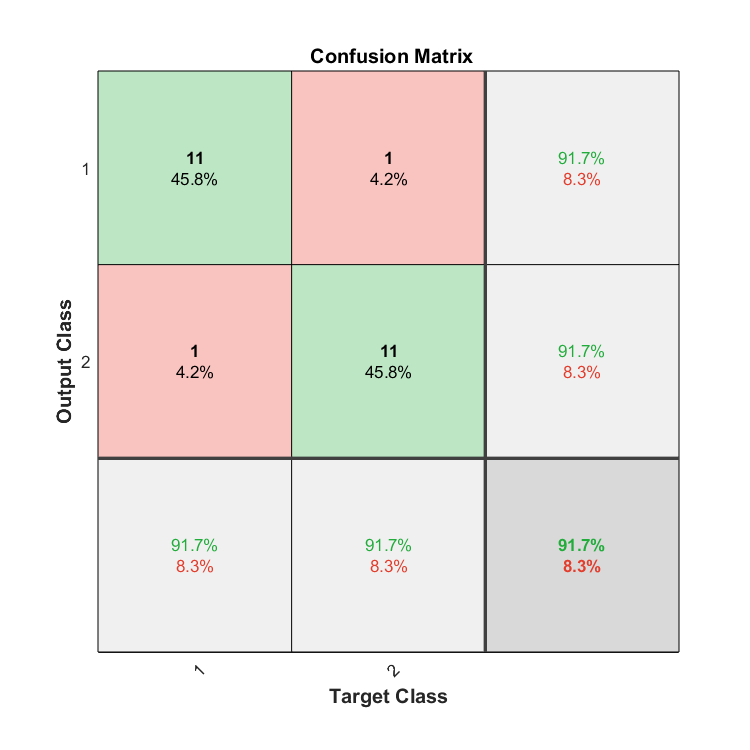

plotconfusion(Ytest_cat,Ytest_pred_cat);

you can repeat this task for different combination of words and vowels or make a for loop to do it automatically but don't forget to report which word and vowel provided the best results. A+word1 give 87.5%. O+word5 give 79.2%. U+word6 give 83.3%.

## Task 2.1: All words classification

Here, you will need to discriminate between the words. In the previous task, you needed to solve a binary classification problem, while here you will be dealing with a multi-class problem. For this assignment, you first need to design a classifier for all words. 

### Making the data marices

As you see only the dataset is different here but we can exactly use the same code as before to complete this task. As we did before with two inputs we should now put all the 9 words together to make the data matrix X. for the output we assign each word to a number from 1 to 9.

% Data matrix with all words
X = [Word1; Word2; Word3; Word4; Word5; Word6; Word7; Word8; Word9];
% Vector of labels, where
Y = [ones(40,1); 2*ones(40,1); 3*ones(40,1); 4*ones(40,1); 5*ones(40,1); 6*ones(40,1); 7*ones(40,1); 8*ones(40,1); 9*ones(40,1)]; 

### Train-test split indices

For this part and the following parts, you can copy/paste the same exact code as before  because we had already developed them for multiclass classification problems.

percent_train_split=70/100;
train_id=[];
test_id=[];
num_classes=length(unique(Y)); 

% loop through the classes
for i=1:num_classes 
    % % finding the indices belonging to each class: use find()
    % % your code below
    ind_i=find(Y==i) ;
    
    % %shuffling the indice
    ind_i_perm=ind_i(randperm(length(ind_i)));
    
    % % the split point for train test
    ind_split=round(percent_train_split*length(ind_i_perm));
    
    % % adding the train ids to the the previous ids 
    train_id=[train_id;ind_i_perm(1:ind_split)];
    
    % % adding the test ids to the the previous ids 
    test_id=[test_id;ind_i_perm(ind_split+1:end)];
    
end

### Split the data

% % splitting the inputs
% complete the codes below
Xtrain=X(train_id, :);
Xtest=X(test_id, :);

% % splitting the labels
Ytrain=Y(train_id);
Ytest=Y(test_id);

### Normalize the data

[Xtrain,mu_train,sigma_train]=zscore(Xtrain);
Xtest=zscore(Xtest);

### Train the classifier 

feel free to change the number of trees or other properties of the function, or even use new classifiers.

% This makes sure we get the same results every time we run the code.
rng default

% How many trees do you want in the forest? 
nTrees = 20;
 
% Train the TreeBagger (Random Forest).
model = TreeBagger( nTrees,Xtrain,Ytrain ...
    , 'Method', 'classification');

### Predict outputs for test data

Ytest_pred_str=model.predict(Xtest);
Ytest_pred=str2double(Ytest_pred_str);

### Turn the numerical outputs to categorical

Ytest_cat=zeros(num_classes, length(Ytest));
Ytest_pred_cat=zeros(num_classes, length(Ytest_pred));

for i=1:num_classes
    Ytest_cat(i, Ytest==i) = 1;
    Ytest_pred_cat(i, Ytest_pred==i) = 1;
end

### Plot the confusion matrix

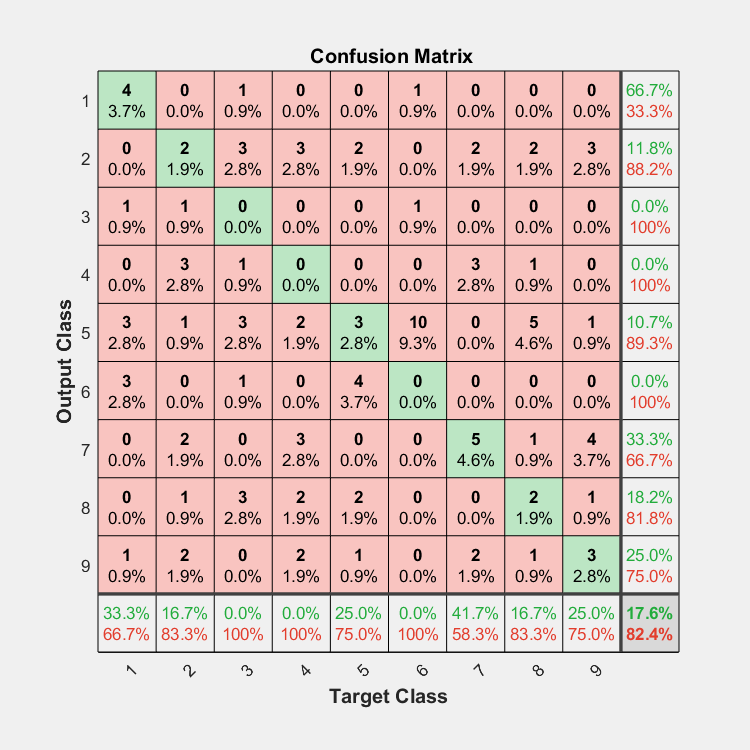

figure; plotconfusion(Ytest_cat,Ytest_pred_cat);

Can you find out how to interpret the confusion matrix in this case?  

## Task 2.2: two word classification

From the confusion matrix you need to select two words for which the performance was the best. Train the new model with only those two words and test it on an independent test set. It is important to look at the features that can be used to separate between words. This information will be useful in the module of voice processing.

We should now make a data matrix only containing the two words with the best performance results. We will assign the outputs to class "1" and "2".

X = [Word1; Word8];
Y = [ones(40,1); 2*ones(40,1)];

### Train-test split indices

percent_train_split=70/100;
train_id=[];
test_id=[];
num_classes=length(unique(Y)); 

% loop through the classes
for i=1:num_classes 
    % % finding the indices belonging to each class: use find()
    % % your code below
    ind_i=find(Y==i) ;
    
    % %shuffling the indice
    ind_i_perm=ind_i(randperm(length(ind_i)));
    
    % % the split point for train test
    ind_split=round(percent_train_split*length(ind_i_perm));
    
    % % adding the train ids to the the previous ids 
    train_id=[train_id;ind_i_perm(1:ind_split)];
    
    % % adding the test ids to the the previous ids 
    test_id=[test_id;ind_i_perm(ind_split+1:end)];
    
end

### Split the data

% % splitting the inputs
% complete the codes below
Xtrain=X(train_id, :);
Xtest=X(test_id, :);

% % splitting the labels
Ytrain=Y(train_id);
Ytest=Y(test_id);

### Normalize the data

[Xtrain,mu_train,sigma_train]=zscore(Xtrain);
Xtest=zscore(Xtest);

### Feature Selection using mRMR

As before, we perform feature selection using mRmR 

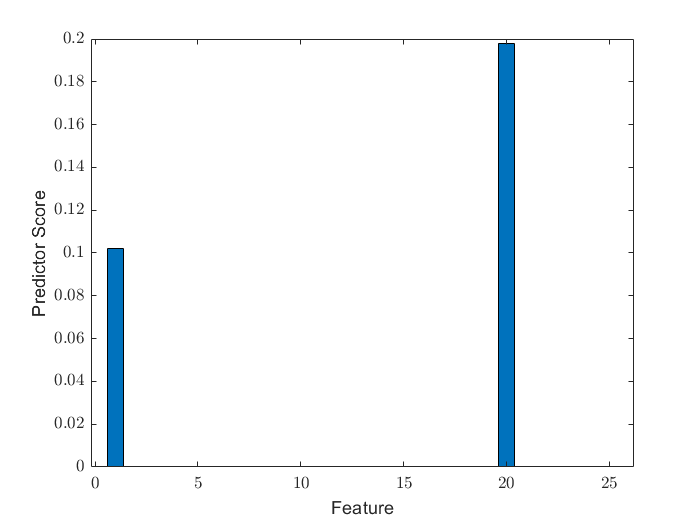

figure;
[idx,scores] = fscmrmr(Xtrain,Ytrain);
bar(idx,scores(idx))% Create bar graph
xlabel('Feature')
set(gca,'TickLabelInterpreter','latex');
ylabel('Predictor Score');
 hold off;

we select 3 features with the best importance and only train the model with them. From the plot above find the 3 indices with the highest score and use them in the code below for feature selection (rerun the whole code  a few times of you don't get a nice plot, the result depend on train/test split to some extent.)

sel_feat=idx(1:3);
Xtrain=Xtrain(:,sel_feat);
Xtest=Xtest(:,sel_feat);

### Train the classifier 

% This makes sure we get the same results every time we run the code.
rng default

% How many trees do you want in the forest? 
nTrees = 20;
 
% Train the TreeBagger (Random Forest).
model = TreeBagger( nTrees,Xtrain,Ytrain ...
    , 'Method', 'classification');

### Predict outputs for test data

Ytest_pred_str=model.predict(Xtest);
Ytest_pred=str2double(Ytest_pred_str);

### Turn the numerical outputs to categorial

Ytest_cat=zeros(num_classes, length(Ytest));
Ytest_pred_cat=zeros(num_classes, length(Ytest_pred));

for i=1:num_classes
    Ytest_cat(i, Ytest==i) = 1;
    Ytest_pred_cat(i, Ytest_pred==i) = 1;
end

### Plot the confusion matrix

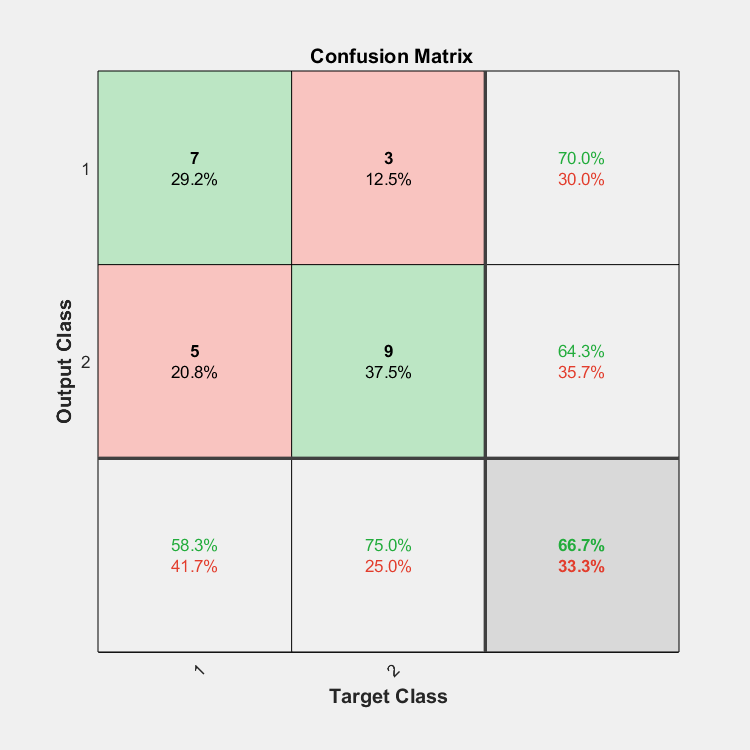

figure; plotconfusion(Ytest_cat,Ytest_pred_cat);